fs=48000;
f0=18000;

data1 = audioread("paper/google2/google2record1641307415407.wav");
data2= audioread("paper/google2/google2record1641029660107.wav")

data2 =     0.0265
    0.0100
   -0.0247
    0.0469
   -0.0227
         0
    0.0373
   -0.0303
    0.0093
    0.0411


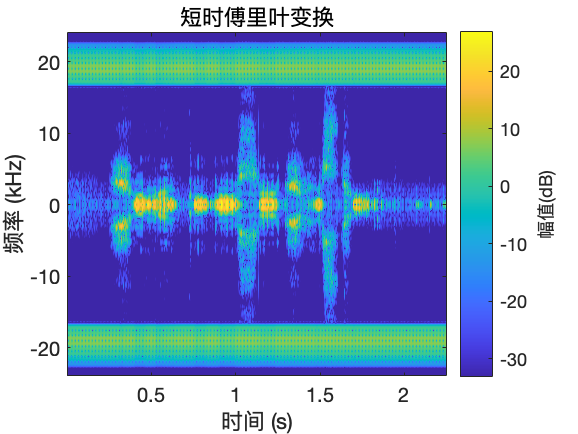




stft(data1, fs,'FFTLength',1024);

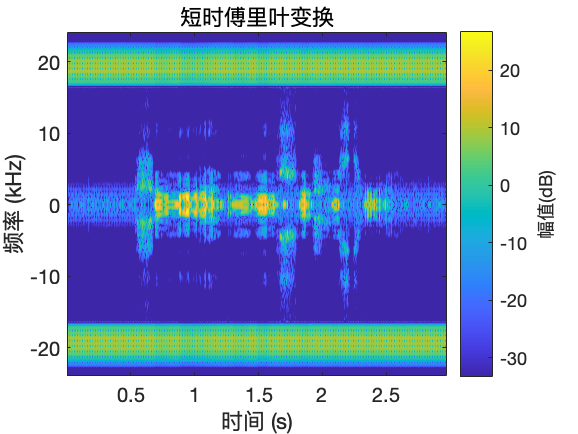

stft(data2, fs,'FFTLength',1024);

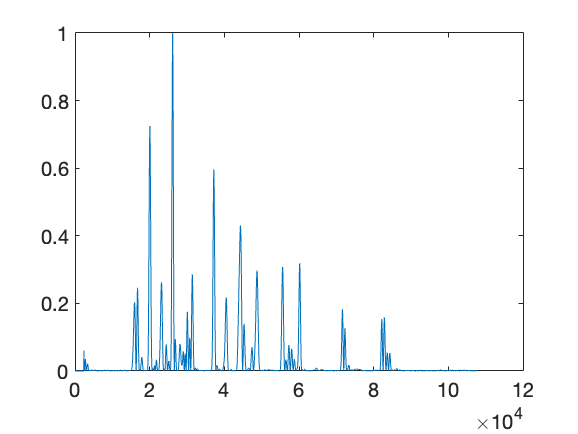


figure;
% power1=getpower(data2(1:size(data1, 1), :));
power1=getpower(data1);
power1=power1';
plot(power1);


% high_data1=highpass(data1, 8000, fs)
% figure;
% plot(high_data1);
low_data1=lowpass(data1, 8000, fs)

low_data1 =    -0.0026
   -0.0022
   -0.0015
   -0.0016
   -0.0030
   -0.0053
   -0.0075
   -0.0088
   -0.0096
   -0.0102


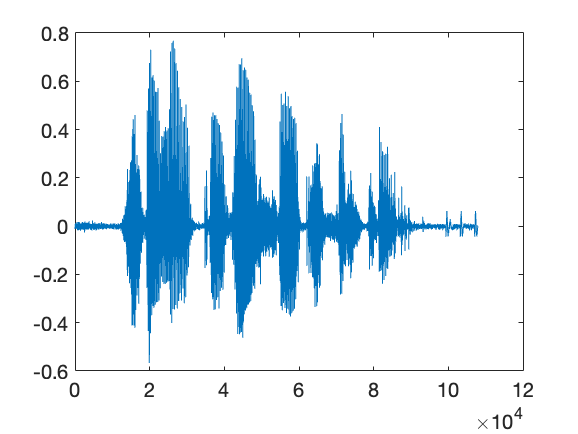

figure;
plot(low_data1);

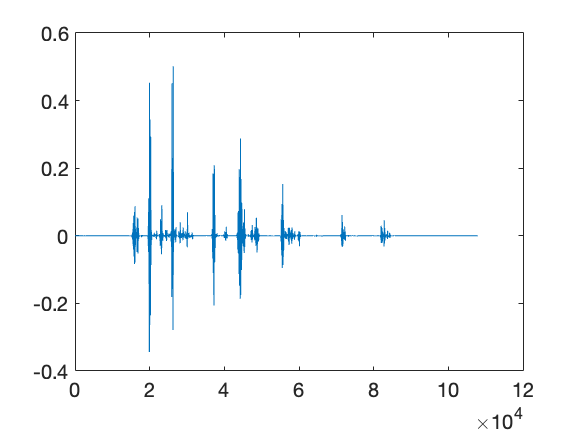

final_data1=power1.*low_data1;
figure;
plot(final_data1);

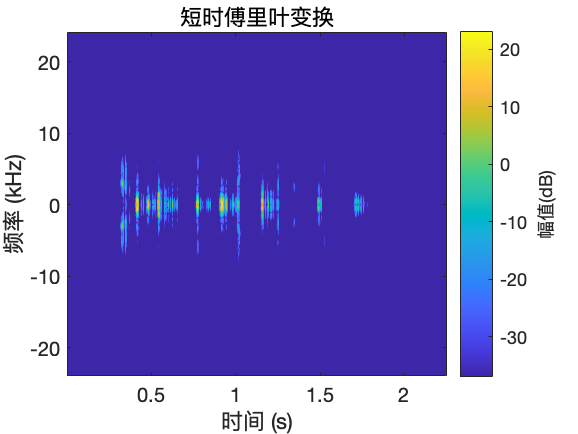

sound(final_data1, fs);
stft(final_data1,fs,'FFTLength',1024);